# **Section 2 - Image Restoration on Blurred License Plate (with noise)**

## Step 1 - Simulating Blurred Image

The blurred image is simulated using a Motion Filter

Read and displaying the original image before degradation process.

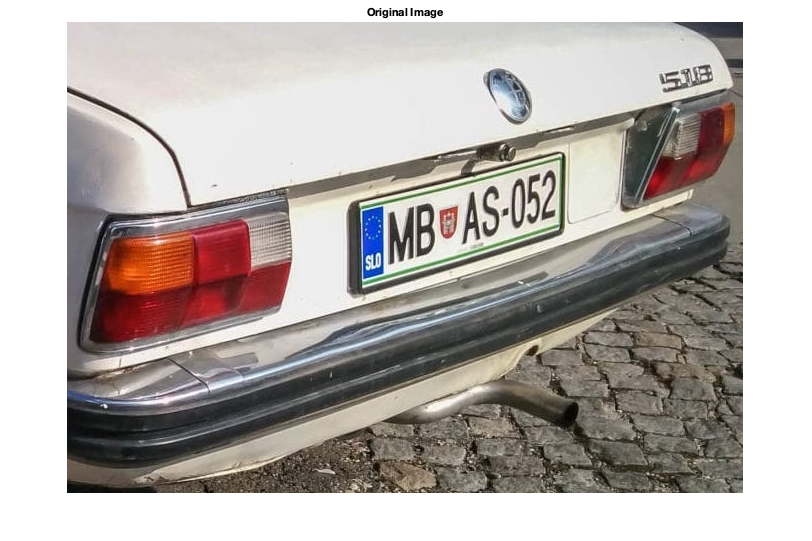

original_image = imread('data/cars_two_a.jpeg');
imshow(original_image);
title('Original Image');

Degrading the original image using the Degrade function with motion blurr.

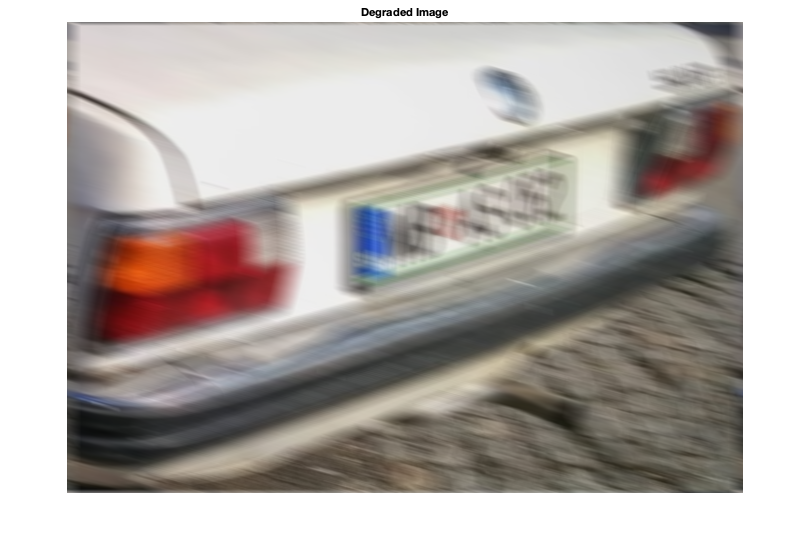

len = 30;       % length of linear motion
theta = -15;     % angle of motion in degrees in a counter-clockwise direction

degraded_image = Degrade(original_image,len,theta);

imshow(degraded_image);
title('Degraded Image');

## Step 2 - Add Noise to The Degraded Image

In this step we add noise into the degraded image using the Noise function

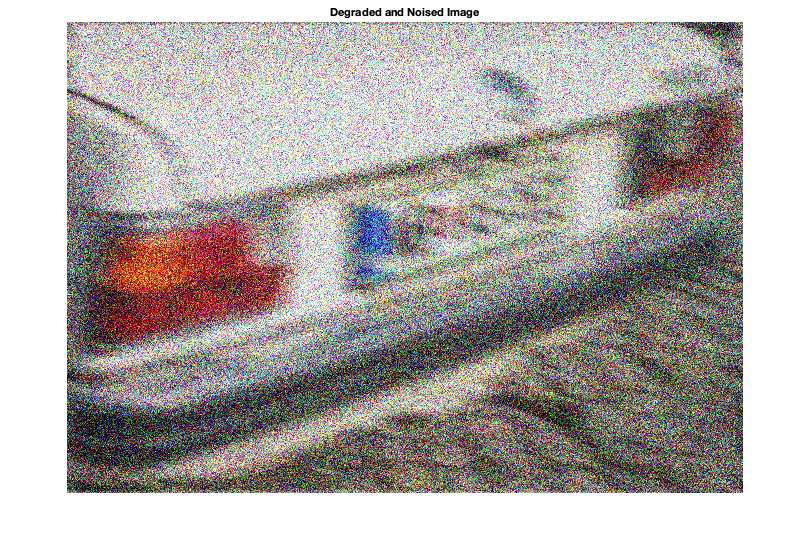

noise_type = 'gaussian';
noise_mean = 0;
noise_variance = 1e-1;

degraded_noised_image = Noise(degraded_image,noise_type,noise_mean,noise_variance);
imshow(degraded_noised_image);
title('Degraded and Noised Image');

Saving the degraded and noised image into a file.

imwrite(degraded_image,'data/cars_two_a_len=30_theta=-15,noise_mean=0,noise_variance=1e-5.jpg')

## Step 3 - Restoring The Image

In this step we will restore the image using Inverse Filter and Wiener Filter. Then we will compare the results

Restoring the degraded noisy image using Inverse Filter.

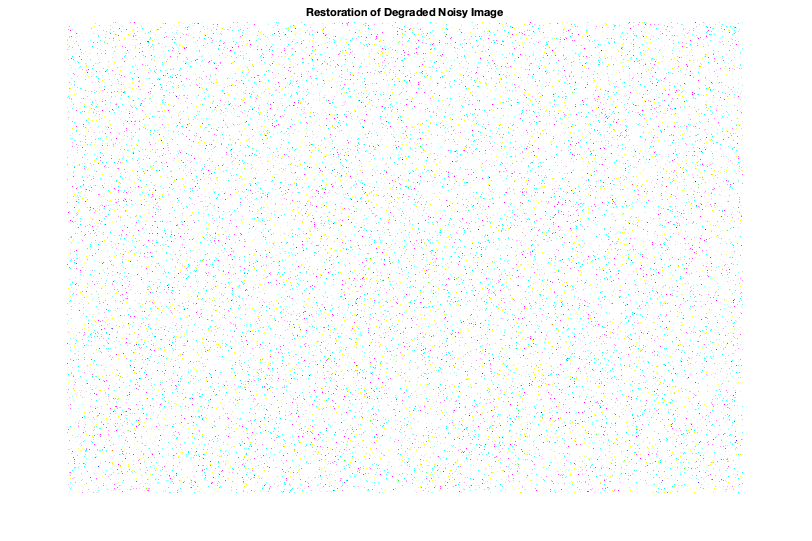

len = 30;
theta = -15;
restored_image_Inverse = Inverse(degraded_noised_image,len,theta);

imshow(restored_image_Inverse)
title('Restoration of Degraded Noisy Image');

Saving the restored image into a file.

imwrite(restored_image_Inverse,'data/cars_two_a_Inverse_len=30_theta=-15,noise_mean=0,noise_variance=1e-5.jpg')

Restoring the degraded noisy image using Wiener Filter.

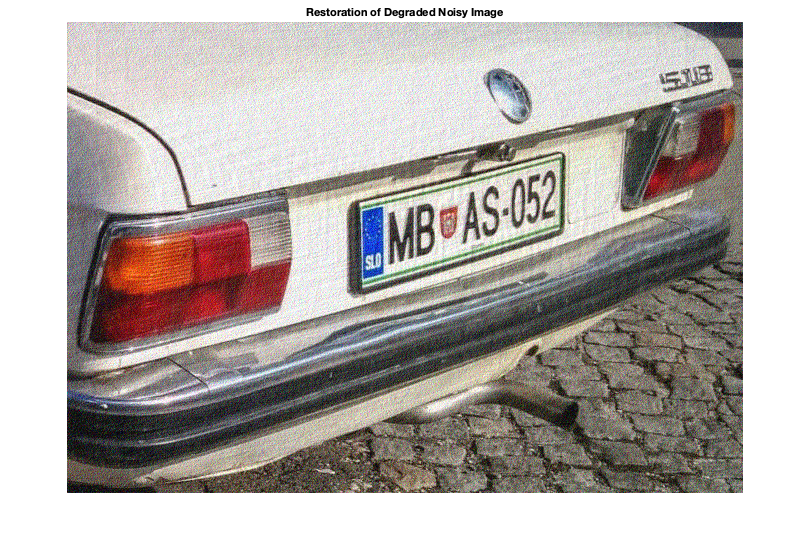

len = 30;
theta = -15;

% Calculating the Signal to Noise Ratio (SNR)
original_image_double = im2double(original_image);
signal_var = var(original_image_double(:));
SNR = noise_variance / signal_var;

restored_image_Wiener = Wiener_Filter(degraded_noised_image,len,theta,SNR);
imshow(restored_image_Wiener)
title('Restoration of Degraded Noisy Image');

Saving the restored image into a file.

imwrite(restored_image_Wiener,'data/cars_two_a_Wiener_len=30_theta=-15,noise_mean=0,noise_variance=1e-5.jpg')